# Obtención de Nulclinas

% Preparación del entorno
clear;    
clc;     
close all;

% Definir los parámetros simbólicos
syms p53 Stat3 Np63 Pp53 N k B ANp63p53 C1 dNp63p53 Dp53 Pstat3 ANp63s Ap53s Dstat3 PNp63 Astat3Np C2 dp53NP C3 dNp63Np63 DNp63
assume(p53 >=0 & Stat3 >=0 & Np63 >=0 & Pp53 >=0 & N >=0 & k >=0 & B >=0 & ANp63p53 >=0 & C1 >=0 & dNp63p53 >=0 & Dp53 >=0 & Pstat3 >=0 & ANp63s >=0 & Ap53s >=0 & Dstat3 >=0 & PNp63 >=0 & Astat3Np >=0 & C2 >=0 & dp53NP >=0 & C3 >=0 & dNp63Np63 >=0 & DNp63>=0)

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) - Dp53*p53;
f2 = (Pstat3 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63;

vars = [p53, Stat3, Np63];

% Resolver las nulclinas simbólicamente
nulclina_p53   = solve(f1 == 0, Np63);      % Nulclina: f1 = 0 → p53 en función de Stat3 y Np63

nulclina_Stat3 = solve(f2 == 0, Np63);    % Nulclina: f2 = 0 → Stat3 en función de p53 y Np63

nulclina_Np63  = solve(f3 == 0, Np63);     % Nulclina: f3 = 0 → Np63 en función de p53 y Stat3


disp('Nulclina de p53:')

Nulclina de p53:


disp(nulclina_p53)

$$-\frac{{\mathrm{Pp}}_{53}+\frac{B\,{p_{53}}^{N}}{k^{N}+{p_{53}}^{N}}-\frac{{\mathrm{Dp}}_{53}\,p_{53}}{C_{1}}}{{\mathrm{ANp63p}}_{53}-\frac{{\mathrm{Dp}}_{53}\,{\mathrm{dNp63p}}_{53}\,p_{53}}{C_{1}}}$$


disp('Nulclina de Stat3:')

Nulclina de Stat3:


disp(nulclina_Stat3)

$$-\frac{{\mathrm{Pstat}}_{3}+\mathrm{Ap53s}\,p_{53}-{\mathrm{Dstat}}_{3}\,{\mathrm{Stat}}_{3}}{\mathrm{ANp63s}}$$


disp('Nulclina de Np63:')

Nulclina de Np63:


disp(nulclina_Np63)

$$-\frac{\sqrt{{\mathrm{DNp}}_{63}}-\sqrt{\left(\mathrm{dp53NP}\,p_{53}+1\right)\,\left({\mathrm{DNp}}_{63}+{\mathrm{DNp}}_{63}\,\mathrm{dp53NP}\,p_{53}+4\,C_{2}\,C_{3}\,{\mathrm{PNp}}_{63}\,{\mathrm{dNp63Np}}_{63}+4\,\mathrm{Astat3Np}\,C_{2}\,C_{3}\,{\mathrm{Stat}}_{3}\,{\mathrm{dNp63Np}}_{63}\right)}+\sqrt{{\mathrm{DNp}}_{63}}\,\mathrm{dp53NP}\,p_{53}}{2\,\left(\sqrt{{\mathrm{DNp}}_{63}}\,{\mathrm{dNp63Np}}_{63}+\sqrt{{\mathrm{DNp}}_{63}}\,{\mathrm{dNp63Np}}_{63}\,\mathrm{dp53NP}\,p_{53}\right)}$$

## Graficas las Neuclinas

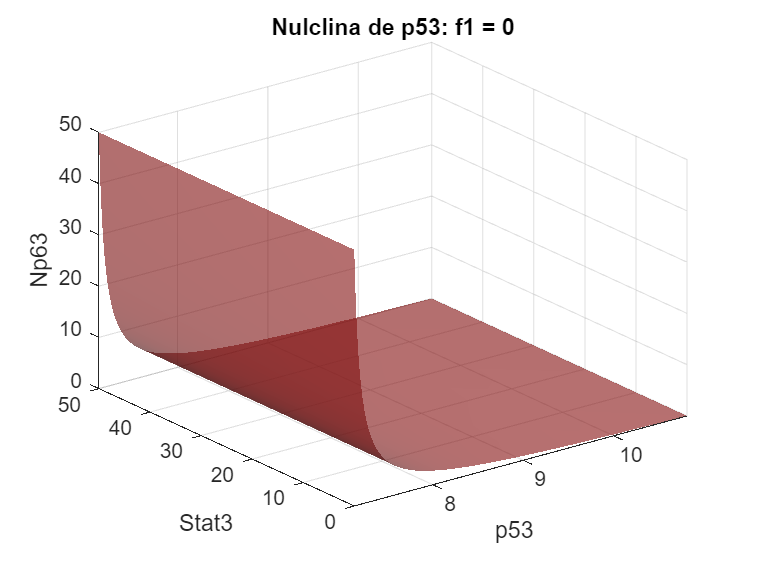

% Definir las nulclinas como ecuaciones implícitas
nulclina_p53   = f1 == 0;     % Nulclina de p53 (f1 = 0)
nulclina_Stat3 = f2 == 0;     % Nulclina de Stat3 (f2 = 0)
nulclina_Np63  = f3 == 0;     % Nulclina de Np63 (f3 = 0)

% Definir valores numéricos de parámetros
params = struct( ...
    'Pp53', 1.1380, 'N', 0.6184, 'k', 1.8558, 'B', 1.6019, ...
    'ANp63p53', 1.3864, 'C1', 0.8905, 'dNp63p53', 1.0944, 'Dp53', 0.1597, ...
    'Pstat3', 0.9819, 'ANp63s', 0.0053, 'Ap53s', 1.1090, 'Dstat3', 0.8895, ...
    'PNp63', 5.7201, 'Astat3Np', 0.9350, 'C2', 1.2659, 'dp53NP', 0.0000, ...
    'C3', 2.8150, 'dNp63Np63', 0.2113, 'DNp63', 3.3663);

% Sustituir parámetros
f1_num = subs(f1, params);
f2_num = subs(f2, params);
f3_num = subs(f3, params);

% Crear funciones anónimas que reciben (p53, Stat3, Np63)
f1_func = matlabFunction(f1_num, 'Vars', [p53, Stat3, Np63]);
f2_func = matlabFunction(f2_num, 'Vars', [p53, Stat3, Np63]);
f3_func = matlabFunction(f3_num, 'Vars', [p53, Stat3, Np63]);

% Crear la malla
range = linspace(0, 50, 200);  
[P53, STAT3, NP63] = meshgrid(range, range, range);

% Evaluar las funciones
F1_vals = f1_func(P53, STAT3, NP63);
F2_vals = f2_func(P53, STAT3, NP63);
F3_vals = f3_func(P53, STAT3, NP63);

% Primera Neuclina
figure;
s1 = isosurface(P53, STAT3, NP63, F1_vals, 0);
p1 = patch(s1);
set(p1, ...
    'FaceColor', [0.85 0.1 0.1], ...   % rojo suave
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.6);                % transparencia

xlabel('p53'); ylabel('Stat3'); zlabel('Np63');
title('Nulclina de p53: f1 = 0');
grid on; axis tight; view(3);
camlight headlight; lighting gouraud;
rotate3d on;

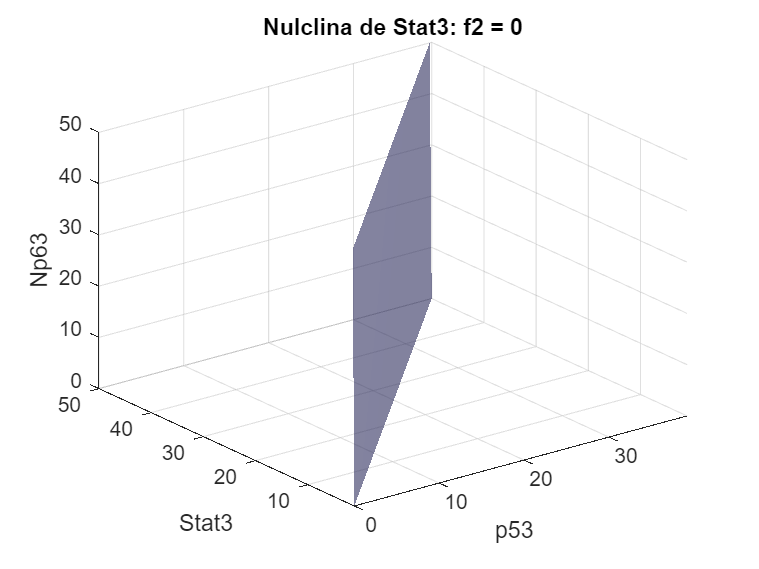


% Segunda Neuclina
figure;
s2 = isosurface(P53, STAT3, NP63, F2_vals, 0);
p2 = patch(s2);
set(p2, ...
    'FaceColor', [0.5 0.5 1], ...  
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.6);             
xlabel('p53'); ylabel('Stat3'); zlabel('Np63');
title('Nulclina de Stat3: f2 = 0');
grid on; axis tight; view(3);
camlight headlight; lighting gouraud;
rotate3d on;

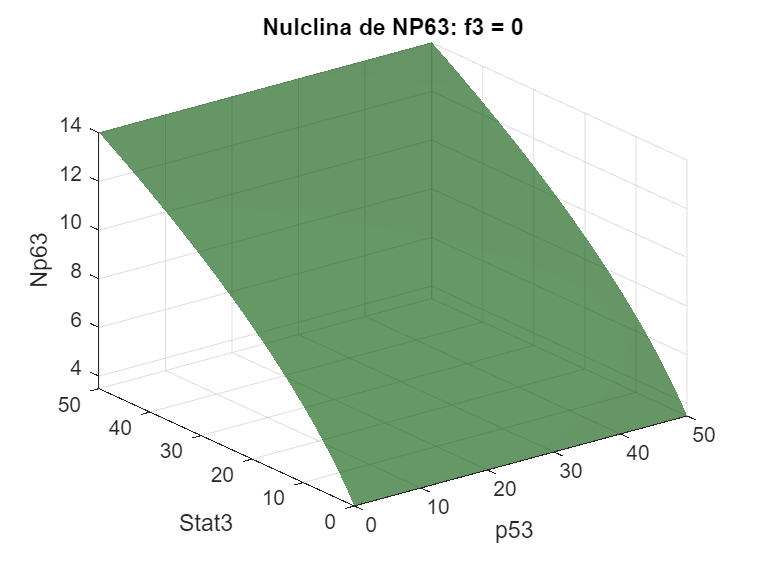


% Tercera Neuclina
figure;
s3 = isosurface(P53, STAT3, NP63, F3_vals, 0);
p3 = patch(s3);
set(p3, ...
    'FaceColor', [0 0.4 0], ...  
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.6);           
xlabel('p53'); ylabel('Stat3'); zlabel('Np63');
title('Nulclina de NP63: f3 = 0');
grid on; axis tight; view(3);
camlight headlight; lighting gouraud;
rotate3d on;

## Intersección de Nulclinas

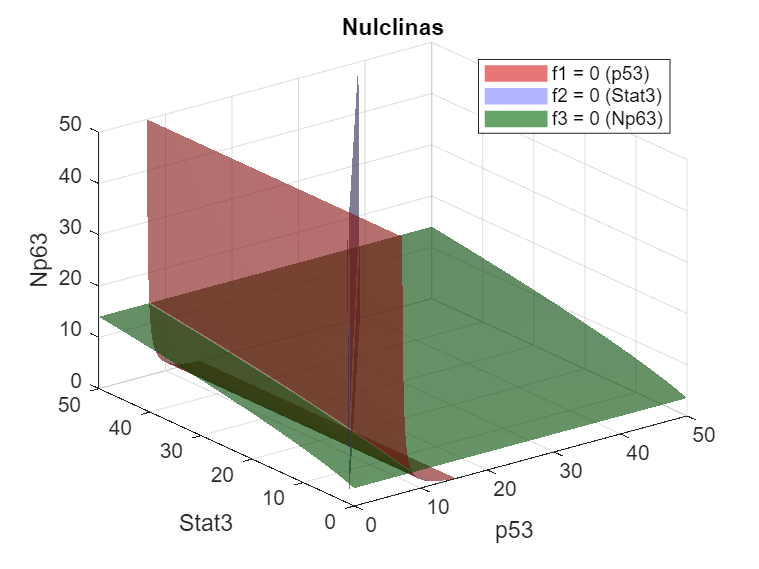

figure;
p1 = patch(isosurface(P53, STAT3, NP63, F1_vals, 0));
set(p1, 'FaceColor', [0.85 0.1 0.1], 'EdgeColor', 'none', 'FaceAlpha', 0.6); hold on;

p2 = patch(isosurface(P53, STAT3, NP63, F2_vals, 0));
set(p2, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none', 'FaceAlpha', 0.6);

p3 = patch(isosurface(P53, STAT3, NP63, F3_vals, 0));
set(p3, 'FaceColor', [0 0.4 0], 'EdgeColor', 'none', 'FaceAlpha', 0.6);

xlabel('p53'); ylabel('Stat3'); zlabel('Np63');
legend([p1 p2 p3], {'f1 = 0 (p53)', 'f2 = 0 (Stat3)', 'f3 = 0 (Np63)'});
title('Nulclinas');
view(3); axis tight; grid on;
camlight headlight; lighting gouraud;
rotate3d on;